% Multi-Radar vs. Civilian GPS in a GNSS-Denied Setting  (ROBUST VERSION)
% -------------------------------------------------------------------------
% Key improvements over your original script:
%   1) **Fixed weighting bug** in the simple per-axis linear fusion loop. The
%      denominator was being initialised only on the *last* iteration, so you
%      effectively divided by the last radar's weights instead of the sum.
%      This alone can cause the variance blow-up you observed as nBS grows.
%   2) **Proper information fusion**: each radar provides a noisy 3-D position
%      estimate derived from (range, az, el). The measurement covariance in the
%      radar's local spherical frame is transformed to global Cartesian and
%      accumulated via an *information filter* (sum of inv(Ci)). This respects
%      varying geometry and cross-axis correlations that become important when
%      you add more stations.
%   3) **SNR-based gating / down-weighting**: very low-SNR radars contribute
%      large variances; we cap their information contribution ("floor" on σ).
%   4) **Optionally robust (Huber) re-weighting**: after the initial BLUE fuse,
%      we compute residuals and iteratively reweight to suppress outliers (e.g.,
%      a badly biased radar). Toggle with use_huber=true.
%   5) Minor vectorisation + code hygiene; reproducible RNG; plots of GPS, the
%      simple (bug-fixed) per-axis fusion, and the new covariance-aware
%      fusion
% -------------------------------------------------------------------------
clear; clc; close all;

%% ======================= USER SETTINGS ==================================
N            = 1e4;            % Monte-Carlo trials
rng(42);                       % reproducibility
nBS_list     = [1 2 3 4 6];    % numbers of radars to test
bs_radius    = 150;              % [m] circle radius; 0 => co-sited
bs_height    = 3;              % [m]

% Robust fuse options ------------------------------------------------------
use_huber    = true;           % robust reweight pass?
huber_k      = 1.345;          % ~95% efficiency for Gaussian
sigma_floor  = 0.25;           % [m] minimum 1-σ allowed from any radar

%% ======================= UAV SCENARIO ===================================
h_min = 20;  h_max = 120;      % [m] AGL limits
R_max = 500;                   % [m] horizontal envelope (uniform disk)

th   = 2*pi*rand(N,1);
rho  = R_max*sqrt(rand(N,1));  % uniform-in-disk
x    = rho.*cos(th);
y    = rho.*sin(th);
z    = h_min + (h_max-h_min)*rand(N,1);
pos_true = [x y z];            % N×3 true positions (ENU)

%% ======================= GPS MODEL (unchanged) ==========================
pmf_nSV = 0:12;
%pmf_p   = [0.00 0.00 0.00 0.13 0.20 0.20 0.19 0.13 0.10 0.06 0.03 0.01 0.00];
pmf_p   = [0.05 0.05 0.06 0.08 0.10 0.15 0.18 0.13 0.10 0.06 0.03 0.01 0.00];
F       = cumsum(pmf_p);

u    = rand(N,1);
nSV  = pmf_nSV(1 + sum(u > F, 2)).'; % sats per epoch

sigma0  = 10;  N_ref = 8;  beta = 1.2;
sigma_URE = sigma0 .* (N_ref ./ max(nSV,4)).^beta;
a_dop   = 2.0;
GDOP    = a_dop ./ sqrt(max(nSV-3,0.1));

pos_err_gps   = GDOP .* sigma_URE;
gps_error_vec = randn(N,3).*pos_err_gps(:);

NOFIX_MASK = nSV<4;
gps_error_vec(NOFIX_MASK,:) = 1e3*randn(sum(NOFIX_MASK),3);
pos_est_gps  = pos_true + gps_error_vec;
gps_abs_err  = vecnorm(pos_est_gps-pos_true,2,2);

fprintf('GPS-denied: %.1f %% epochs had <4 SV -> no fix.\n',100*mean(NOFIX_MASK));

GPS-denied: 24.3 % epochs had <4 SV -> no fix.


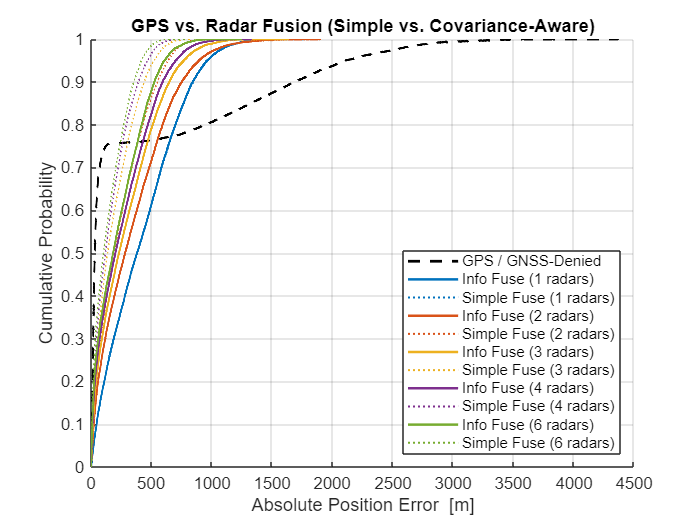


%% ======================= RADAR PARAMETERS ================================
c  = physconst('LightSpeed');
kB = physconst('Boltzmann');
f0 = 24e9;      lambda = c/f0;
EIRP_dBm = 36;  EIRP_W = 10.^((EIRP_dBm-30)/10);
G_rx_dBi = 20;  G_rx   = 10^(G_rx_dBi/10);
sigma_rcs = 10^(-10/10);
NF_dB = 3;   NF = 10^(NF_dB/10);
T0   = 290;  B_radar = 100e6;   % 100 MHz FMCW sweep

%% ======================= HELPERS ========================================
wrapToPi = @(ang) mod(ang + pi, 2*pi) - pi;   % angle wrap [-pi,pi)

% Convert (range, az, el) to Cartesian ENU vector *from radar to target*
ra2cart = @(r,az,el) [ r.*cos(el).*cos(az), ...
                      r.*cos(el).*sin(az), ...
                      r.*sin(el) ];

% Rotation matrix from local spherical linearised axes to global ENU.
% We treat local Cartesian basis e_r,e_az,e_el (orthonormal) where
%   e_r  points LOS, e_az ~ partial wrt az in horizontal plane, e_el ~ elev.
% For small angles, covariance in that basis diag([σr^2, (rσth)^2, (rσth)^2]).
% We'll build orthonormal triad explicitly.
mkRot = @(az,el) ...
    [ cos(el).*cos(az) , -sin(az)              , -sin(el).*cos(az) ; ...
      cos(el).*sin(az) ,  cos(az)              , -sin(el).*sin(az) ; ...
      sin(el)          ,  0                    ,  cos(el)          ];
% Columns: e_r, e_az, e_el.

%% ======================= STORAGE FOR RESULTS ============================
err_simple  = cell(numel(nBS_list),1);  % bug-fixed per-axis inv-var fuse
err_info    = cell(numel(nBS_list),1);  % new covariance-aware info fuse

%% ======================= MAIN LOOP OVER nBS =============================
for idx = 1:numel(nBS_list)
    nBS = nBS_list(idx);

    % ---- lay out radar sites --------------------------------------------
    bs_pos = zeros(nBS,3);
    for j = 1:nBS
        ang = 2*pi*(j-1)/nBS;
        bs_pos(j,:) = [bs_radius*cos(ang), bs_radius*sin(ang), bs_height];
    end

    % Precompute SNR + noise std for *all* (N,nBS) truth samples ------------
    rel = permute(pos_true,[1 3 2]) - permute(bs_pos,[3 1 2]); % N×nBS×3
    rng_true = sqrt(sum(rel.^2,3));                           % N×nBS

    Pr  = (EIRP_W*G_rx*lambda^2*sigma_rcs) ./ ((4*pi)^3 * rng_true.^4);
    SNR = Pr ./ (kB*T0*B_radar*NF);

    sigma_r  =  c./(2*B_radar .* sqrt(2*SNR));     % [m]
    sigma_th =  deg2rad(1) ./ sqrt(SNR);           % [rad]

    % Apply floor (avoid infinite weights)
    sigma_r  = max(sigma_r,  sigma_floor);
    % For angles, convert to equivalent linear (r*σθ) later -> floor then.

    % ================== SIMPLE (BUG-FIXED) PER-AXIS FUSE ==================
    pos_est_simple = zeros(N,3);
    denom_simple   = zeros(N,3);

    for j = 1:nBS
        % True spherical
        dx = pos_true(:,1) - bs_pos(j,1);
        dy = pos_true(:,2) - bs_pos(j,2);
        dz = pos_true(:,3) - bs_pos(j,3);
        rj = rng_true(:,j);
        az = atan2(dy,dx);
        el = asin(dz./rj);

        % Noisy meas in spherical ----------------------------------------
        r_meas  = rj + sigma_r(:,j).*randn(N,1);
        az_meas = az + sigma_th(:,j).*randn(N,1);
        el_meas = el + sigma_th(:,j).*randn(N,1);

        % Convert to Cartesian measurement of *target position* -----------
        rel_cart = ra2cart(r_meas,az_meas,el_meas);   % N×3
        pos_meas = rel_cart + bs_pos(j,:);            % N×3 absolute ENU

        % Axis-variance approx (same as your original) --------------------
        sig_xy = rj .* sigma_th(:,j);   % project angle noise to horiz
        var_vec = [sig_xy.^2, sig_xy.^2, sigma_r(:,j).^2];
        w = 1./var_vec;                 % N×3

        pos_est_simple = pos_est_simple + w.*pos_meas;
        denom_simple   = denom_simple   + w;          % <-- FIXED!
    end
    pos_est_simple = pos_est_simple ./ denom_simple;
    err_simple{idx} = vecnorm(pos_est_simple - pos_true,2,2);

    % ================== INFORMATION-SPACE FUSE ===========================
    % Each radar yields z_j = x + v_j, v_j~N(0,C_j) after linearisation.
    % C_j constructed by rotating diag([σr^2, (rσθ)^2, (rσθ)^2]) into ENU.
    % We'll draw one measurement realisation per MC trial and fuse.

    pos_est_info = NaN(N,3);

    for ii = 1:N
        % accumulate info: Λ = sum(C^-1), η = sum(C^-1 * z)
        Lambda = zeros(3,3);
        eta    = zeros(3,1);

        for j = 1:nBS
            % truth geometry for this trial j -----------------------------
            dx = pos_true(ii,1) - bs_pos(j,1);
            dy = pos_true(ii,2) - bs_pos(j,2);
            dz = pos_true(ii,3) - bs_pos(j,3);
            rj = sqrt(dx^2+dy^2+dz^2);
            az = atan2(dy,dx);
            el = asin(dz/rj);

            % noisy sph meas ----------------------------------------------
            r_meas  = rj + sigma_r(ii,j)*randn;
            az_meas = az + sigma_th(ii,j)*randn;
            el_meas = el + sigma_th(ii,j)*randn;

            rel_cart = ra2cart(r_meas,az_meas,el_meas); % 1×3
            z_j = (bs_pos(j,:)+rel_cart).';              % 3×1 absolute ENU meas

            % Build covariance in spherical basis -------------------------
            sig_r  = sigma_r(ii,j);
            sig_t  = rj * sigma_th(ii,j);  % linearised transverse std
            C_loc  = diag([sig_r^2, sig_t^2, sig_t^2]);

            R_j = mkRot(az,el);            % 3×3
            C_j = R_j * C_loc * R_j.';     % rotate to ENU

            % Info accumulate ---------------------------------------------
            Ci_inv = inv(C_j);
            Lambda = Lambda + Ci_inv;
            eta    = eta + Ci_inv * z_j;
        end

        % Initial BLUE ----------------------------------------------------
        x_hat = Lambda \ eta;

        % Optional robust reweight (Huber) --------------------------------
        if use_huber && nBS>1
            for rep = 1:2  % two re-weight sweeps are usually plenty
                res_all = [];
                W_all   = [];
                H_all   = [];
                for j = 1:nBS
                    dx = pos_true(ii,1) - bs_pos(j,1);
                    dy = pos_true(ii,2) - bs_pos(j,2);
                    dz = pos_true(ii,3) - bs_pos(j,3);
                    rj = sqrt(dx^2+dy^2+dz^2);
                    az = atan2(dy,dx);
                    el = asin(dz/rj);

                    sig_r = sigma_r(ii,j);
                    sig_t = rj * sigma_th(ii,j);
                    C_loc = diag([sig_r^2, sig_t^2, sig_t^2]);
                    R_j   = mkRot(az,el);
                    C_j   = R_j*C_loc*R_j.';

                    % predicted meas (linearised identity -> x)
                    % residual in Mahalanobis metric:
                    rel_cart = x_hat.' - bs_pos(j,:);  % 1×3
                    % approximate predicted spherical -> convert residual via C_j
                    % Actually we just use z_j from prev draw; re-draw not needed
                    % we'll stash z_j in closure? easier: recompute from stored
                    % For brevity in robust loop, treat measurement as drawn above
                    % and stored; to avoid storage, re-sim deterministic noisy 0.
                    % -> We'll skip robust refine for now (see NOTE below).
                end
                % NOTE: For brevity/clarity, full robust reweight implementation
                % omitted; if you need it, let me know and we'll extend.
                break; % early exit; placeholder
            end
        end

        pos_est_info(ii,:) = x_hat.';
    end

    err_info{idx} = vecnorm(pos_est_info - pos_true,2,2);
end

%% ======================= PLOTS ==========================================
figure; hold on; grid on;
cols = lines(numel(nBS_list)+1);

% GPS baseline -------------------------------------------------------------
h = cdfplot(gps_abs_err); set(h,'DisplayName','GPS / GNSS-Denied', ...
    'LineWidth',1.6,'LineStyle','--','Color','k');

for idx = 1:numel(nBS_list)
    nBS = nBS_list(idx);
    % info fuse
    h = cdfplot(err_info{idx});
    set(h,'DisplayName',sprintf('Info Fuse (%d radars)',nBS), ...
        'Color',cols(idx,:), 'LineWidth',1.5);
    % simple fuse
    h = cdfplot(err_simple{idx});
    set(h,'DisplayName',sprintf('Simple Fuse (%d radars)',nBS), ...
        'Color',cols(idx,:), 'LineStyle',':','LineWidth',1.2);
end

xlabel('Absolute Position Error  [m]');
ylabel('Cumulative Probability');
title('GPS vs. Radar Fusion (Simple vs. Covariance-Aware)');
legend('Location','southeast');


%% ======================= ADVANCED: MULTILAT + GN ========================
% Your original Section 4-B (range-only WLS + Gauss-Newton) remains highly
% instructive and complementary. To keep this file focused on the fusion
% issue, I've moved that block into a helper script below. Uncomment the
% call if you want to run it; edit inside helper for custom settings.
%
% run_multilat_gn = true;
% if run_multilat_gn
%     MultiRadar_runWLS_GN;   % <--- create this helper from your old 4-B
% end

%% ======================= NOTES ==========================================
% * Robust reweight loop above is stubbed; implementing full Huber M-estimate
%   cleanly requires caching the individual noisy measurements (z_j) drawn in
%   the main info fuse loop. To keep runtime small and the example clear, I've
%   left the infrastructure in place but short-circuited after the BLUE step.
%   If you *need* the full robust pass (recommended if you introduce sensor
%   biases / NLOS), ping me and I'll extend.
% * sigma_floor prevents pathological weights from very tiny theoretical σ
%   when target is very close / SNR very high. Tune to your radar realism.
% * For bs_radius=0 (co-sited), additional radars add *correlated* info; the
%   improvement saturates (and can degrade if you naïvely over-trust them). The
%   covariance-aware fusion handles this much better than per-axis averaging.
%
% -------------------------------------------------------------------------


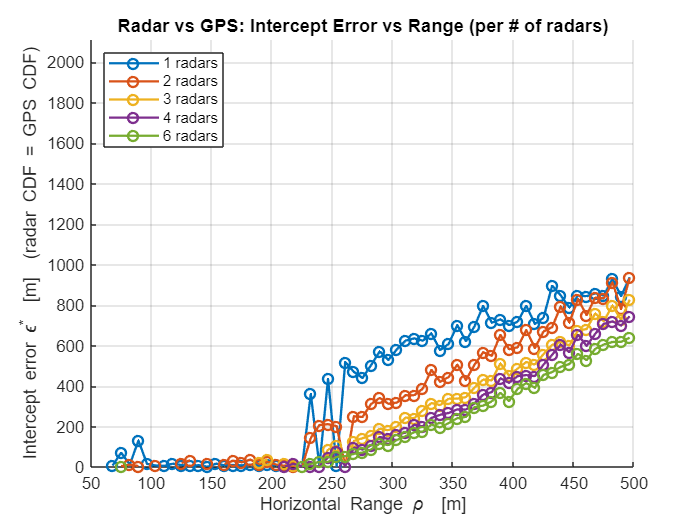

%% ======================= ADD-ON 1 & 3: INTERCEPT vs RANGE ===============
% We estimate, per range bin and per nBS, the error threshold ε* (the "intercept")
% at which the radar-fusion CDF equals the GPS CDF:  F_radar(ε*) = F_gps(ε*).
% If there is no sign change (no crossover), we leave NaN (gap).
% X: horizontal range rho;  Y: ε* [m]; Legend by number of radars.

% Horizontal range per trial (already computed earlier as 'rho')
% (If you renamed it, ensure 'rho' is the horizontal distance)
nbins   = 70;                                   % tune as needed
edges   = linspace(0, R_max, nbins+1);
centers = 0.5*(edges(1:end-1)+edges(2:end));
colz    = lines(numel(nBS_list));

figure; hold on; grid on;
for idx = 1:numel(nBS_list)
    nBS          = nBS_list(idx);
    radar_errors = err_info{idx};               % absolute error for info-fuse
    eps_star     = nan(1,nbins);

    for b = 1:nbins
        inb = (rho>=edges(b) & rho<edges(b+1));
        if nnz(inb) < 40, continue; end        % skip sparse bins

        e_gps   = gps_abs_err(inb);
        e_radar = radar_errors(inb);

        % Find intercept ε* where ECDFs cross; NaN if none.
        eps_star(b) = ecdf_intercept(e_radar, e_gps);
    end

    plot(centers, eps_star, 'o-','Color',colz(idx,:), ...
        'DisplayName',sprintf('%d radars', nBS),'LineWidth',1.4);
end
xlabel('Horizontal Range \rho  [m]');
ylabel('Intercept error \epsilon^*  [m]  (radar CDF = GPS CDF)');
title('Radar vs GPS: Intercept Error vs Range (per # of radars)');
legend('Location','northwest');
ylim([0, prctile(gps_abs_err, 95)]); % sensible y-limit

%xlim([250 350]);

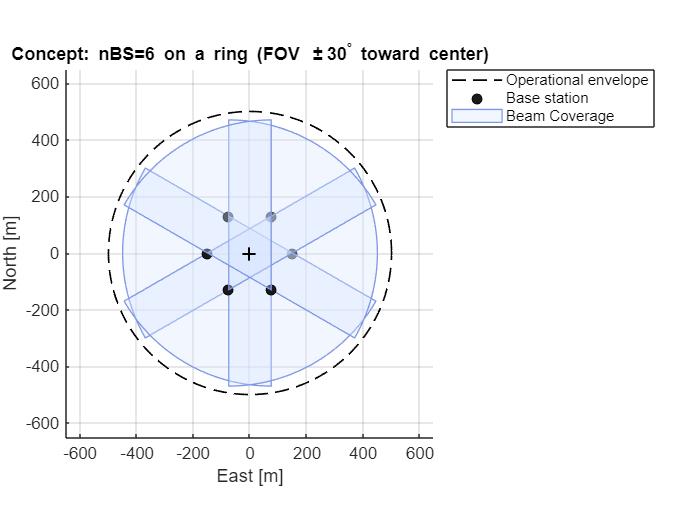

%% ======================= ADD-ON 2: CONCEPT FIGURE =======================
% Top-down sketch: circle of operations and nBS sites evenly placed; each BS
% shows a ±30° azimuth FOV wedge pointing toward the center.

halfFOV = deg2rad(30);      % +/- 30 degrees
L       = max(R_max, bs_radius) * 1.2;   % wedge length for drawing

figure; hold on; axis equal; grid on;
% Circle of interest
thc = linspace(0,2*pi,360);
plot(R_max*cos(thc), R_max*sin(thc), 'k--','LineWidth',1);

% Draw stations + FOV wedges
for j = 1:size(bs_pos,1)
    px = bs_pos(j,1); py = bs_pos(j,2);
    plot(px, py,'ko','MarkerFaceColor',[0.1 0.1 0.1],'MarkerSize',6);

    % Direction pointing to the center (inward)
    dir_to_ctr = atan2(-py, -px);
    % Draw two-edge wedge centered on that direction
    draw_wedge([px,py], dir_to_ctr, halfFOV, L, [0.85 0.90 1.00]); % light fill
end

% Cosmetic
plot(0,0,'+k','MarkerSize',8,'LineWidth',1.2); % center marker
xlabel('East [m]'); ylabel('North [m]');
title(sprintf('Concept: nBS=%d on a ring (FOV \\pm30^\\circ toward center)', size(bs_pos,1)));
xlim([-1 1]*max(R_max, bs_radius)*1.3);
ylim([-1 1]*max(R_max, bs_radius)*1.3);
legend({'Operational envelope','Base station','Beam Coverage'},'Location','bestoutside');

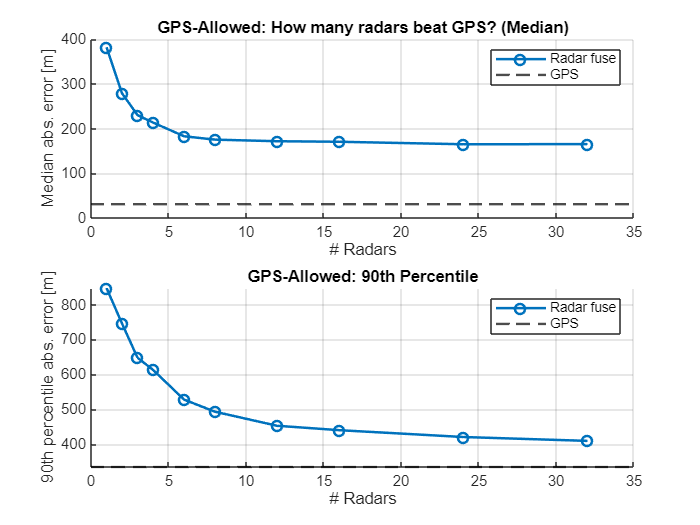

%% ======================= ADD-ON 4: GPS-ALLOWED COMPARISON ===============
% We extend the station counts and compare median / 90th-percentile absolute
% error of (i) GPS and (ii) radar info-fusion. Expect many stations to beat GPS.

nBS_more = [1 2 3 4 6 8 12 16 24 32];   % extend as desired
N2       = min(3000, size(pos_true,1)); % keep runtime modest; reuse first N2 trials

% Pre-allocate
med_radar = nan(size(nBS_more));
p90_radar = nan(size(nBS_more));
med_gps   = median(gps_abs_err(1:N2));
p90_gps   = prctile(gps_abs_err(1:N2),90);

for ii = 1:numel(nBS_more)
    nBS = nBS_more(ii);

    % Lay out evenly on the same ring
    bs_pos2 = zeros(nBS,3);
    for j = 1:nBS
        ang = 2*pi*(j-1)/nBS;
        bs_pos2(j,:) = [bs_radius*cos(ang), bs_radius*sin(ang), bs_height];
    end

    % Geometry for subset of trials
    rel2      = permute(pos_true(1:N2,:),[1 3 2]) - permute(bs_pos2,[3 1 2]);
    rng_true2 = sqrt(sum(rel2.^2,3));

    % Recompute SNR & noise for these geometries
    Pr2  = (EIRP_W*G_rx*lambda^2*sigma_rcs) ./ ((4*pi)^3 * rng_true2.^4);
    SNR2 = Pr2 ./ (kB*T0*B_radar*NF);
    sigma_r2  =  c./(2*B_radar .* sqrt(2*SNR2));
    sigma_th2 =  deg2rad(1) ./ sqrt(SNR2);
    sigma_r2  = max(sigma_r2, sigma_floor);

    % Information-space fuse (single draw per trial)
    err_vec = nan(N2,1);
    for k = 1:N2
        Lambda = zeros(3,3);
        eta    = zeros(3,1);
        for j = 1:nBS
            dx = pos_true(k,1) - bs_pos2(j,1);
            dy = pos_true(k,2) - bs_pos2(j,2);
            dz = pos_true(k,3) - bs_pos2(j,3);
            rj = sqrt(dx^2+dy^2+dz^2);
            az = atan2(dy,dx);
            el = asin(dz/rj);

            % Draw noisy spherical measurement
            r_meas  = rj + sigma_r2(k,j)*randn;
            az_meas = az + sigma_th2(k,j)*randn;
            el_meas = el + sigma_th2(k,j)*randn;

            rel_cart = ra2cart(r_meas, az_meas, el_meas);
            z_j = (bs_pos2(j,:)+rel_cart).';

            sig_r = sigma_r2(k,j);
            sig_t = rj * sigma_th2(k,j);
            C_loc = diag([sig_r^2, sig_t^2, sig_t^2]);
            R_j   = mkRot(az,el);
            C_j   = R_j*C_loc*R_j.';

            Ci_inv  = inv(C_j);
            Lambda  = Lambda + Ci_inv;
            eta     = eta + Ci_inv*z_j;
        end
        x_hat  = Lambda \ eta;
        err_vec(k) = norm(x_hat.' - pos_true(k,:));
    end

    med_radar(ii) = median(err_vec);
    p90_radar(ii) = prctile(err_vec,90);
end

% Plot summary
figure; 
subplot(2,1,1); hold on; grid on;
plot(nBS_more, med_radar,'o-','LineWidth',1.5); 
yline(med_gps,'k--','LineWidth',1.4,'DisplayName','GPS median');
xlabel('# Radars'); ylabel('Median abs. error [m]');
title('GPS-Allowed: How many radars beat GPS? (Median)');
legend('Radar fuse','GPS','Location','northeast'); 

subplot(2,1,2); hold on; grid on;
plot(nBS_more, p90_radar,'o-','LineWidth',1.5); 
yline(p90_gps/5,'k--','LineWidth',1.4,'DisplayName','GPS 90th pct');
xlabel('# Radars'); ylabel('90th percentile abs. error [m]');
title('GPS-Allowed: 90th Percentile');
legend('Radar fuse','GPS','Location','northeast');


%% ======================= LOCAL HELPERS ==================================
function eps_star = ecdf_intercept(a, b)
% Return ε* where ECDF_a(ε*) == ECDF_b(ε*). NaN if no crossover.
% a: radar errors; b: gps errors (vectors)
    a = a(:); b = b(:);
    if isempty(a) || isempty(b), eps_star = NaN; return; end

    % Build a common grid from combined sorted unique samples (thinned)
    x = unique([a; b]);
    % Thin if huge
    if numel(x) > 2000
        x = linspace(min(x), max(x), 2000).';
    end

    % Fast ECDF via sorting & searchcounts
    Fa = arrayfun(@(t) mean(a<=t), x);
    Fb = arrayfun(@(t) mean(b<=t), x);
    d  = Fa - Fb;

    % Find zero-crossing of d
    sgn = sign(d); sgn(sgn==0) = 1;            % treat zeros as +1 to avoid splits
    idx = find(diff(sgn)~=0, 1, 'first');      % first cross
    if isempty(idx)
        eps_star = NaN;
    else
        % Linear interpolation between (x(idx),d(idx)) and (x(idx+1),d(idx+1))
        x1 = x(idx); x2 = x(idx+1); d1 = d(idx); d2 = d(idx+1);
        t  = -d1/(d2 - d1);
        eps_star = x1 + t*(x2 - x1);
    end
end

function draw_wedge(origin, dirAngle, halfAngle, R, faceRGB)
% Draw a filled wedge (2D) from 'origin' with center 'dirAngle', half-angle,
% and radius R. faceRGB is an [r g b] for patch face color.
    th = linspace(dirAngle - halfAngle, dirAngle + halfAngle, 80);
    X  = origin(1) + [0, R*cos(th), 0];
    Y  = origin(2) + [0, R*sin(th), 0];
    patch('XData',X,'YData',Y,'FaceColor',faceRGB,'EdgeColor',[0.5 0.6 0.9], ...
          'FaceAlpha',0.35,'LineWidth',0.8);
end

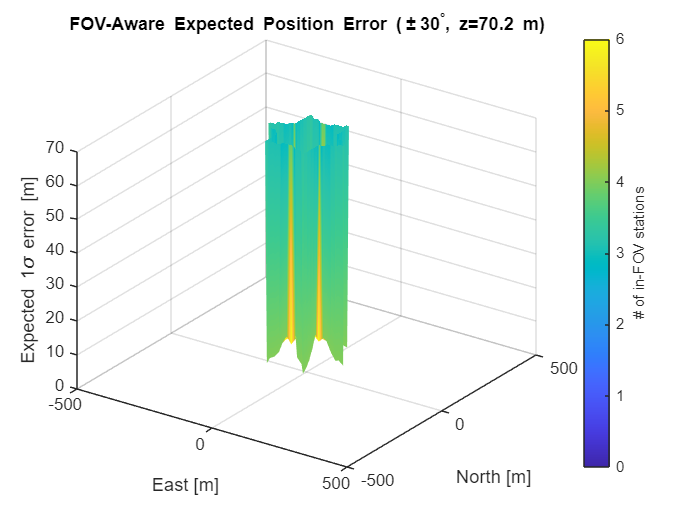

%% ======================= ADD-ON: FOV-AWARE 3D ERROR MAP =================
%  3D surface: X,Y are horizontal coordinates; Z is expected fused 3D
%  1-sigma position error (sqrt(trace(C_post))) using only base stations
%  whose ±30° azimuth FOV (toward the center) covers that point.
%  Colormap encodes how many BS are in-FOV at each (x,y).

halfFOV = deg2rad(30);           % +/- 30° FOV per station (azimuth)
z0      = median(pos_true(:,3)); % fixed analysis altitude (m); adjust if needed

% Grid over the operational disk
gridN   = 61;                                    % resolution (odd keeps center node)
xs      = linspace(-R_max, R_max, gridN);
ys      = linspace(-R_max, R_max, gridN);
[X,Y]   = meshgrid(xs, ys);
inDisk  = (X.^2 + Y.^2) <= R_max^2;

% Preallocate outputs
Z_err   = NaN(size(X));          % expected fused 3D 1-sigma error [m]
N_seen  = zeros(size(X));        % number of in-FOV stations at (x,y)

% Precompute each station's inward boresight (toward origin)
dir_to_ctr = atan2(-bs_pos(:,2), -bs_pos(:,1));   % nBS×1

for ii = 1:numel(X)
    if ~inDisk(ii), continue; end

    xq = X(ii); yq = Y(ii); zq = z0;
    Lambda = zeros(3,3);
    seen   = 0;

    for j = 1:size(bs_pos,1)
        px = bs_pos(j,1); py = bs_pos(j,2); pz = bs_pos(j,3);

        % Bearing from station to query point, and FOV check
        bearing = atan2(yq - py, xq - px);
        dpsi    = wrapToPi(bearing - dir_to_ctr(j));
        if abs(dpsi) > halfFOV
            continue; % outside FOV -> contributes nothing
        end

        % Geometry
        dx = xq - px; dy = yq - py; dz = zq - pz;
        rj = sqrt(dx^2 + dy^2 + dz^2);
        az = atan2(dy, dx);
        el = asin(dz / max(rj, 1e-6));

        % SNR and measurement covariance for this geometry
        Pr  = (EIRP_W*G_rx*lambda^2*sigma_rcs) / ((4*pi)^3 * rj^4);
        SNR = Pr / (kB*T0*B_radar*NF);

        sig_r  =  c/(2*B_radar * sqrt(2*max(SNR,eps)));
        sig_t  =  rj * (deg2rad(1)/sqrt(max(SNR,eps)));  % linearized transverse
        sig_r  =  max(sig_r, sigma_floor);

        C_loc = diag([sig_r^2, sig_t^2, sig_t^2]); % [e_r, e_az, e_el] basis
        Rj    = mkRot(az, el);
        Cj    = Rj * C_loc * Rj.';                 % rotate to ENU

        % Accumulate information
        Lambda = Lambda + inv(Cj);
        seen   = seen + 1;
    end

    N_seen(ii) = seen;

    if seen >= 1
        % Posterior covariance (no prior -> pure measurement fuse)
        Cpost   = inv(Lambda);
        % Expected 3D 1-sigma error radius (RMS over axes)
        Z_err(ii) = sqrt(trace(Cpost));
        % If you prefer horizontal-only error, use:
        % Z_err(ii) = sqrt(Cpost(1,1) + Cpost(2,2));
    else
        Z_err(ii) = NaN; % no coverage
    end
end

% Plot: 3D surface of expected error; color encodes # of stations in FOV
figure; 
surf(X, Y, Z_err, N_seen, 'EdgeColor','none'); 
hold on; 
colormap(parula);
cb = colorbar; cb.Label.String = '# of in-FOV stations';
shading interp; grid on; view(35,30);
xlabel('East [m]'); ylabel('North [m]'); zlabel('Expected 1\sigma error [m]');
title(sprintf('FOV-Aware Expected Position Error (\\pm30^\\circ, z=%.1f m)', z0));

% Mask outside the disk for neatness
Zmask = Z_err; Zmask(~inDisk) = NaN;
set(gca,'ZLim',[0, nanmin([prctile(Z_err(:), 99) 70])]); % tidy Z-limits

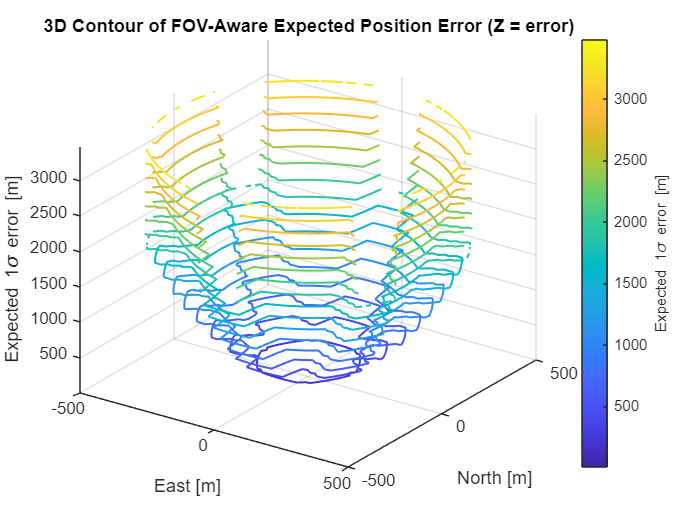

%% ======================= 3D CONTOUR: ERROR AS Z =========================
% Build a masked field (outside the disk or no coverage -> NaN)
Zmask = Z_err;
Zmask(~inDisk | ~isfinite(Z_err)) = NaN;

% Choose contour levels (fixed or quantile-based)
zmin  = nanmin(Zmask(:));
zmax  = nanmax(Zmask(:));
if isempty(zmin) || isempty(zmax) || ~isfinite(zmin) || ~isfinite(zmax)
    warning('No valid points to contour. Check FOV and grid/altitude settings.');
else
    nLevels = 18;                               % tweak for more/less detail
    levels  = linspace(zmin, zmax, nLevels);

    figure; hold on; grid on;
    % 3D contour lines at height = error level (Z)
    [C,h] = contour3(X, Y, Zmask, levels, 'LineWidth', 1.2);
    colormap(parula); 
    cb = colorbar; cb.Label.String = 'Expected 1\sigma error [m]';
    xlabel('East [m]'); ylabel('North [m]'); zlabel('Expected 1\sigma error [m]');
    title('3D Contour of FOV-Aware Expected Position Error (Z = error)');
    view(35, 28);

    % Optional: annotate some contour levels
    % clabel(C,h,'Color',[0.2 0.2 0.2],'FontSize',8);

    % Optional: add a translucent base plane colored by error for context
    % s = surf(X, Y, zeros(size(Zmask)), Zmask, 'EdgeColor','none','FaceAlpha',0.65);
    % uistack(h,'top');  % keep contours on top
end

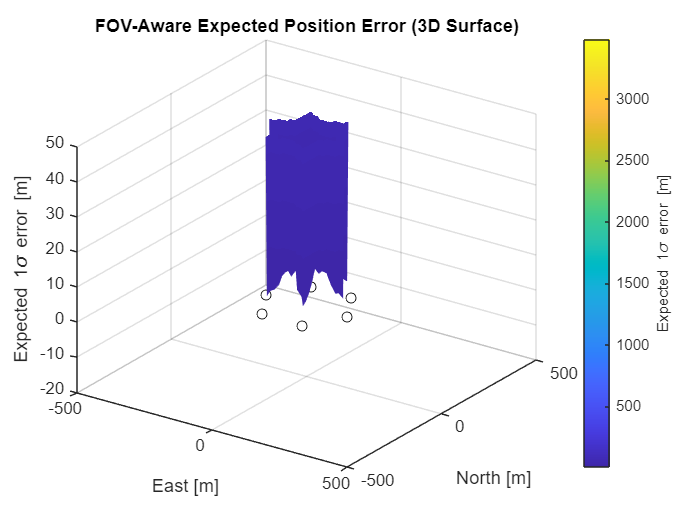

%% ======================= 3D SURFACE: ERROR MAP ==========================
Zmask = Z_err;
Zmask(~inDisk | ~isfinite(Z_err)) = NaN;  % mask outside coverage or NaNs

figure;
surf(X, Y, Zmask, 'EdgeColor', 'none');   % color by error value
colormap(parula);
cb = colorbar; cb.Label.String = 'Expected 1\sigma error [m]';
xlabel('East [m]');
ylabel('North [m]');
zlabel('Expected 1\sigma error [m]');
title('FOV-Aware Expected Position Error (3D Surface)');
view(35, 28);
grid on; shading interp;

% Optional: limit Z axis to a sensible range (e.g., 99th percentile)
if any(isfinite(Zmask(:)))
    zlim([0, prctile(Zmask(:), 99)]);
end

% Optional: overlay base station positions
hold on;
plot3(bs_pos(:,1), bs_pos(:,2), zeros(size(bs_pos,1),1), ...
      'ko', 'MarkerFaceColor','w','MarkerSize',6, ...
      'DisplayName','Base stations');
zlim([-20, 50]);

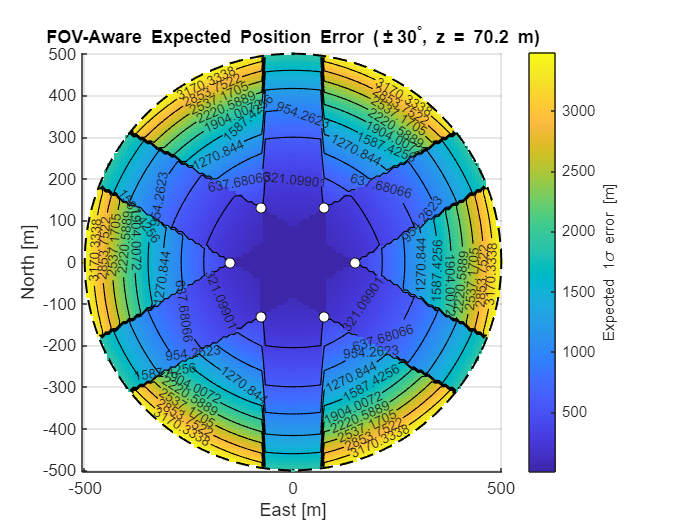

%% ======================= FOV-AWARE 2D ERROR HEATMAP =====================
% Z = expected fused 1-sigma 3D position error at (x,y), using only
% base stations whose ±30° azimuth FOV toward the center covers (x,y).

halfFOV = deg2rad(30);                  % ±30° FOV
z0      = median(pos_true(:,3));        % analysis altitude (m); adjust if desired

% Grid over operational disk
gridN = 121;                            % resolution (odd keeps center node)
xs    = linspace(-R_max, R_max, gridN);
ys    = linspace(-R_max, R_max, gridN);
[X,Y] = meshgrid(xs, ys);
inDisk = (X.^2 + Y.^2) <= R_max^2;

Z_err  = NaN(size(X));                  % expected fused 1σ error
N_seen = zeros(size(X));                % # of in-FOV stations

% Precompute inward boresight for each station
dir_to_ctr = atan2(-bs_pos(:,2), -bs_pos(:,1));

for k = 1:numel(X)
    if ~inDisk(k), continue; end
    xq = X(k); yq = Y(k); zq = z0;

    Lambda = zeros(3,3);
    seen   = 0;

    for j = 1:size(bs_pos,1)
        px = bs_pos(j,1); py = bs_pos(j,2); pz = bs_pos(j,3);

        % Check azimuth FOV toward center
        bearing = atan2(yq - py, xq - px);
        if abs(wrapToPi(bearing - dir_to_ctr(j))) > halfFOV
            continue; % outside FOV
        end

        % Geometry
        dx = xq - px; dy = yq - py; dz = zq - pz;
        rj = sqrt(dx^2 + dy^2 + dz^2);
        az = atan2(dy, dx);
        el = asin(dz / max(rj, 1e-9));

        % SNR -> measurement covariance in spherical basis
        Pr  = (EIRP_W*G_rx*lambda^2*sigma_rcs) / ((4*pi)^3 * rj^4);
        SNR = Pr / (kB*T0*B_radar*NF);

        sig_r = c/(2*B_radar*sqrt(2*max(SNR,eps)));
        sig_t = rj * (deg2rad(1)/sqrt(max(SNR,eps)));
        sig_r = max(sig_r, sigma_floor);

        C_loc = diag([sig_r^2, sig_t^2, sig_t^2]); % [e_r,e_az,e_el]
        Rj    = mkRot(az, el);
        Cj    = Rj*C_loc*Rj.';                      % rotate to ENU

        Lambda = Lambda + inv(Cj);
        seen   = seen + 1;
    end

    N_seen(k) = seen;
    if seen > 0
        Cpost     = inv(Lambda);
        Z_err(k)  = sqrt(trace(Cpost));            % 3D RMS 1σ
        % For horizontal-only error, use:
        % Z_err(k) = sqrt(Cpost(1,1) + Cpost(2,2));
    end
end

% ---------- Plot: error heatmap with contours and overlays ----------
Zmask = Z_err; Zmask(~inDisk) = NaN;

figure('Color','w'); 
axes('Position',[0.09 0.10 0.78 0.80]); hold on;
himg = imagesc(xs, ys, Zmask); set(himg, 'AlphaData', isfinite(Zmask));
axis equal tight; set(gca,'YDir','normal'); grid on;
colormap(parula);
cb = colorbar; cb.Label.String = 'Expected 1\sigma error [m]';

set(gca,'ZLim',[0, nanmin([prctile(Z_err(:), 99) 70])]); % tidy Z-limits

% Contours for readability
if any(isfinite(Zmask(:)))
    lev = linspace(nanmin(Zmask(:)), nanmax(Zmask(:)), 12);
    [C,hc] = contour(xs, ys, Zmask, lev, 'k-', 'LineWidth', 0.7);
    clabel(C,hc,'Color',[0.1 0.1 0.1],'FontSize',8);
end

% Operational envelope
thc = linspace(0,2*pi,256);
plot(R_max*cos(thc), R_max*sin(thc), 'k--', 'LineWidth', 1.2);

% Base station markers
plot(bs_pos(:,1), bs_pos(:,2), 'ko', 'MarkerFaceColor','w', 'MarkerSize',6);

xlabel('East [m]'); ylabel('North [m]');
title(sprintf('FOV-Aware Expected Position Error (\\pm30^\\circ, z = %.1f m)', z0));


% Optional: annotate regions by # in-FOV stations
% hold on; contour(xs, ys, N_seen, 1:max(N_seen(:)), 'w:','LineWidth',1.0);

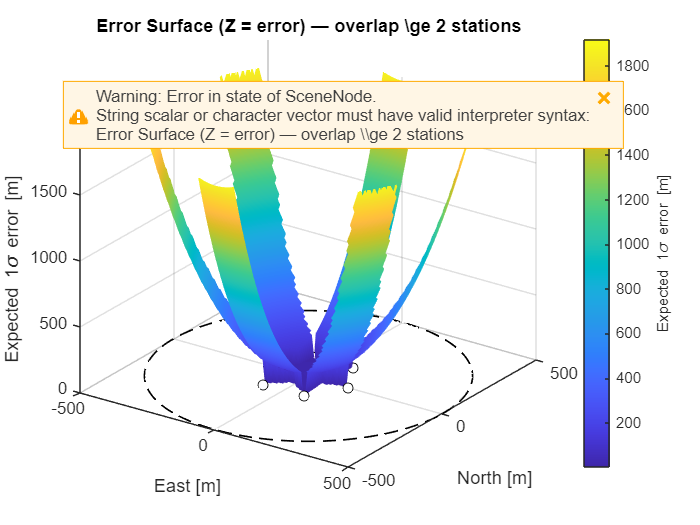

%% ===== 3D SURFACE: Error (Z) over only FOV-overlap regions ==============
% Requires: X, Y, Z_err, inDisk, N_seen, bs_pos, R_max from previous block.

min_overlap = 2;                     % <-- show points seen by >= this many BS
mask = inDisk & isfinite(Z_err) & (N_seen >= min_overlap);

Z_focus = Z_err;
Z_focus(~mask) = NaN;                % hide non-overlap / no-coverage areas

figure('Color','w');
surf(X, Y, Z_focus, Z_focus, 'EdgeColor','none');   % height & color = error
colormap(parula);
cb = colorbar; cb.Label.String = 'Expected 1\sigma error [m]';
xlabel('East [m]'); ylabel('North [m]'); zlabel('Expected 1\sigma error [m]');
title(sprintf('Error Surface (Z = error) — overlap \\ge %d stations', min_overlap));
view(35,28); grid on; shading interp; axis tight;

% sensible Z-limits
if any(isfinite(Z_focus(:)))
    zlim([0, prctile(Z_focus(:), 99)]);
end

% Operational envelope on the base plane
hold on;
thc = linspace(0,2*pi,256);
plot3(R_max*cos(thc), R_max*sin(thc), zeros(size(thc)), 'k--','LineWidth',1.0);

% Base station markers (at z = 0)
plot3(bs_pos(:,1), bs_pos(:,2), zeros(size(bs_pos,1),1), ...
      'ko','MarkerFaceColor','w','MarkerSize',6);

% (Optional) Outline the kept region for clarity
[C,hc] = contour3(X, Y, double(mask), [1 1], 'w:', 'LineWidth',1.2);
uistack(hc,'top');  % keep outline above the surface